# Convolution

## Convolution of two discrete signals

Given two discrete rectangual signals $g[k]$ and $h[k]$ with

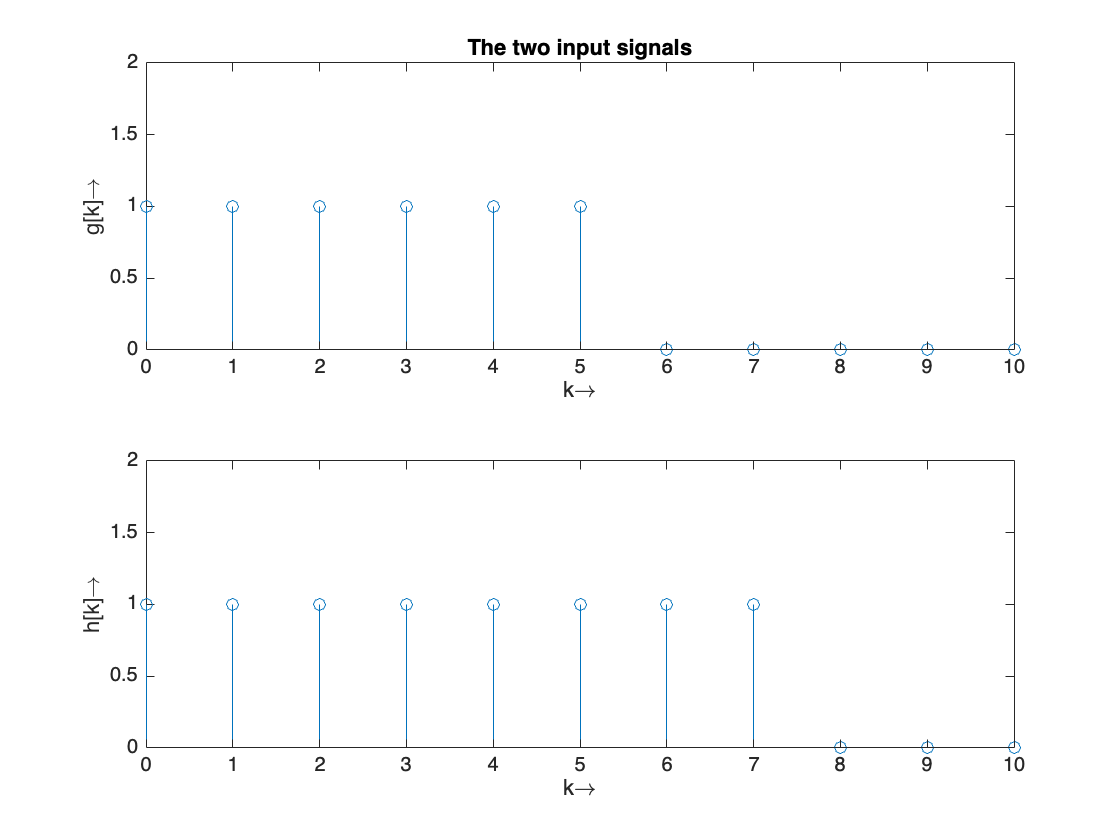

k = 0:10;
g = zeros(size(k));
g(k<6) = 1;
h = zeros(size(k));
h(k<8) = 1;

figure
ax1 = subplot(211);
stem(k, g)
xlabel('k\rightarrow')
ylabel('g[k]\rightarrow')
title('The two input signals')
ax2 = subplot(212);
stem(k, h)
xlabel('k\rightarrow')
ylabel('h[k]\rightarrow')
axis([0, k(end), 0, 2])
linkaxes([ax1, ax2])

The convolution of these two discrete signals is calculated as


$$y[k] = g[k] \ast h[k] = \sum\limits_{k = -\infty}^{+\infty} g[\kappa]\cdot h[k-\kappa]$$


In Matlab the convolutional sum can be easily calculated using the `conv()` method. According to this definition of the lenght of the output vector of `conv()` is `lenght(g)+length(h)-1`.

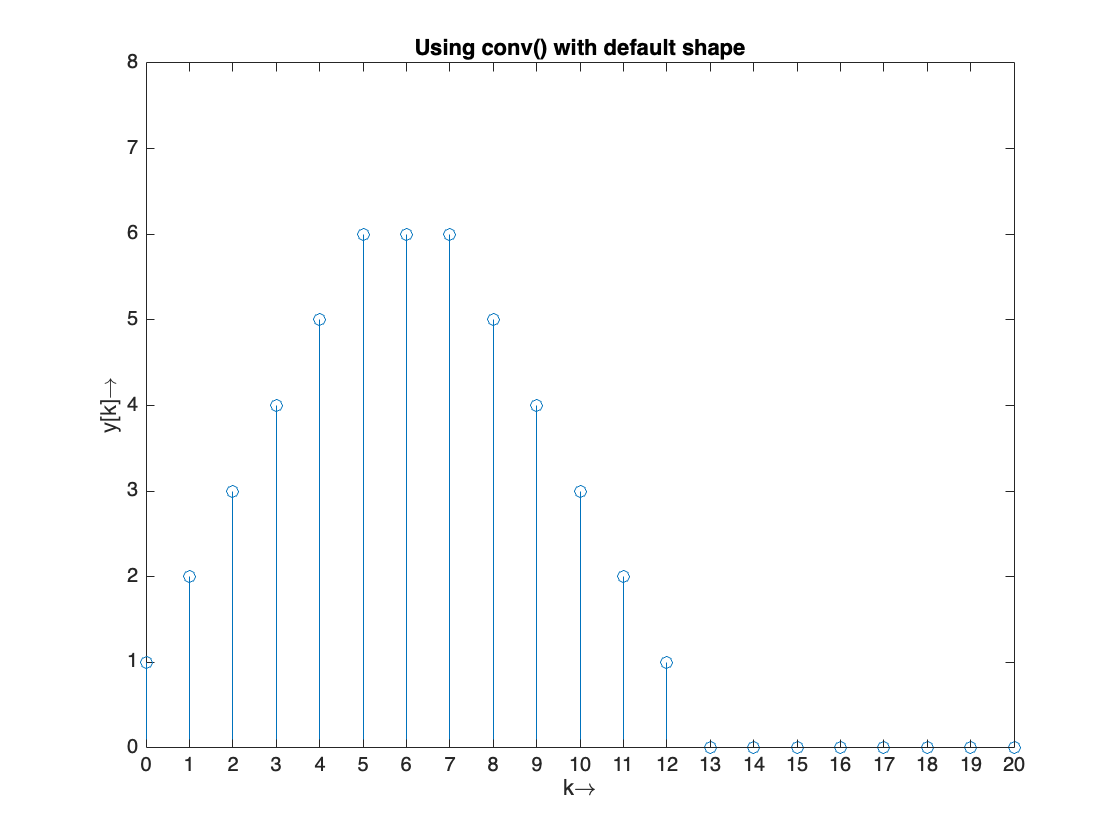

y = conv(g, h);
k = 0:length(g)+length(h)-2;

figure
stem(k, y)
xlabel('k\rightarrow')
ylabel('y[k]\rightarrow')
title('Using conv() with default shape')
axis([0, k(end), 0, 8])
set(gca, 'XTick', k)

In some situations it is desirable that the length of the output signal is limited to the length of one of the input signals (e.g. the first one). This can be achieved by setting the `shape` property of the `conv()` method to `'same'`. This property only works when `length(g) > length(h)`.

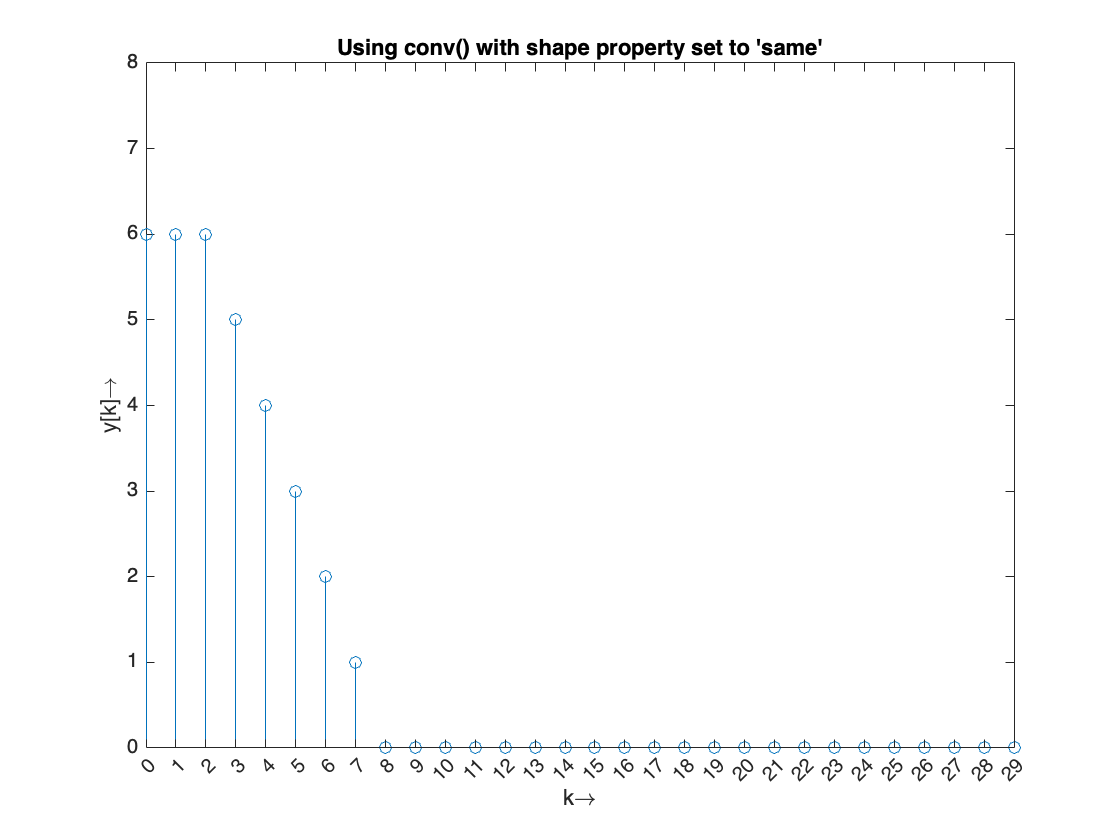

g = zeros(1, 30);
g(k<6) = 1;
h = zeros(1, 10);
h(k<8) = 1;

y = conv(g, h, 'same');
k = 0:length(g)-1;

figure
stem(k, y)
xlabel('k\rightarrow')
ylabel('y[k]\rightarrow')
title("Using conv() with shape property set to 'same'")
axis([0, k(end), 0, 8])
set(gca, 'XTick', k)

In order to only calculate the convolution of the overlapped region of the two signals, the `shape` property can be set to `'valid'`. This may be especially useful if the second signal has minimum length (which would be seven in our example).

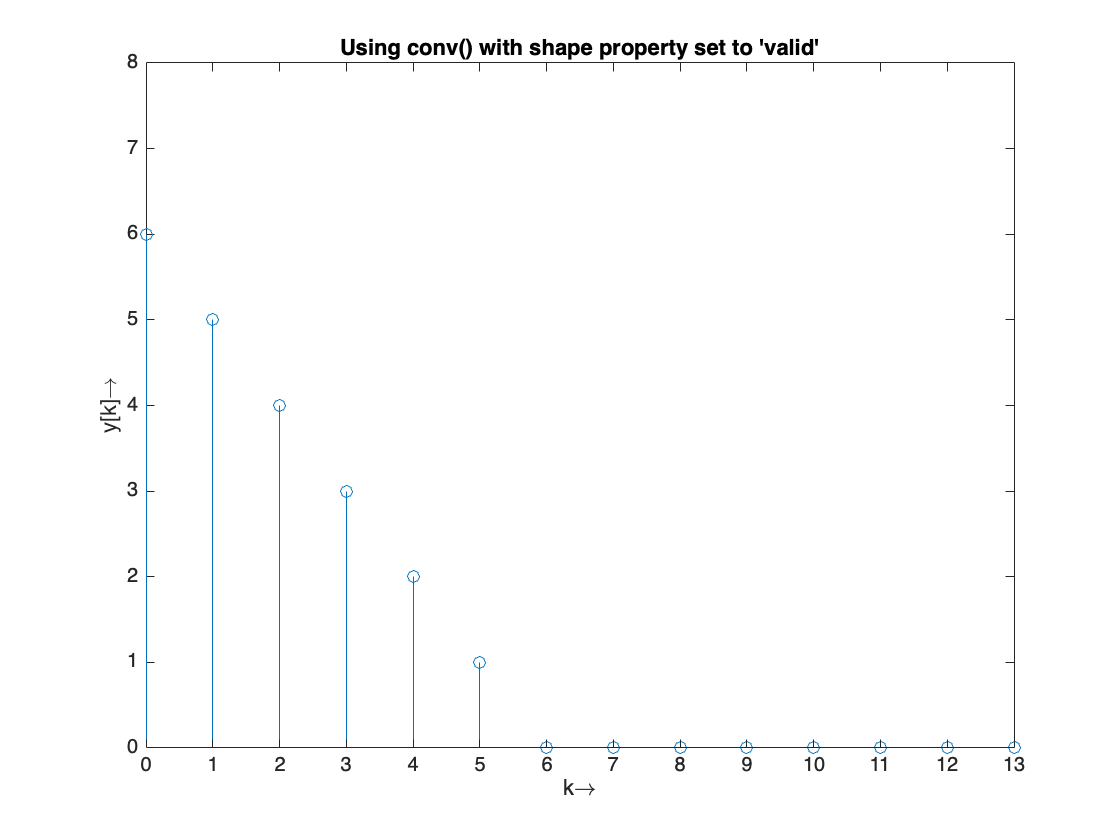

g = zeros(1, 20);
g(k<6) = 1;
h = ones(1, 7);

y = conv(g, h, 'valid');
k = 0:length(g)-length(h);

figure
stem(k, y)
xlabel('k\rightarrow')
ylabel('y[k]\rightarrow')
title("Using conv() with shape property set to 'valid'")
axis([0, k(end), 0, 8])
set(gca, 'XTick', k)

## Approximate the convolution of two continuous-time signals

The calculation of the convolution of two continuous-time signals is not possible with a tool like Matlab. However, it is possible to approximate the result by using sampled versions of the respective input signals.

### Convolution of two rectangular signals

As a first example, we consider the two rectangular signals $g(t)$ and $h(t)$ with


$$g(t) = \mathrm{rect}\left(\frac{t}{16}\right) \qquad\mbox{and}\qquad h(t) = \mathrm{rect}\left(\frac{t-4}{8}\right)$$


Since we cannot implement these two signals in Matlab, we have to consider sampled versions of them


$$g[k] = g(k\cdot T_\mathrm{s}) \qquad\mbox{and}\qquad h[k] = h(k\cdot T_\mathrm{s})$$


The sampling period $T_\mathrm{s}$ has to be set properly, which could be $T_\mathrm{s}=10\cdot 10^{-3}$ in our case. In order to ilustrate the influence of different definitions of the time axis, we define the function $g(t)$ for times between $-15\leq t \leq 20$ and $h(t)$ for times between $-5\leq t\leq 10$.

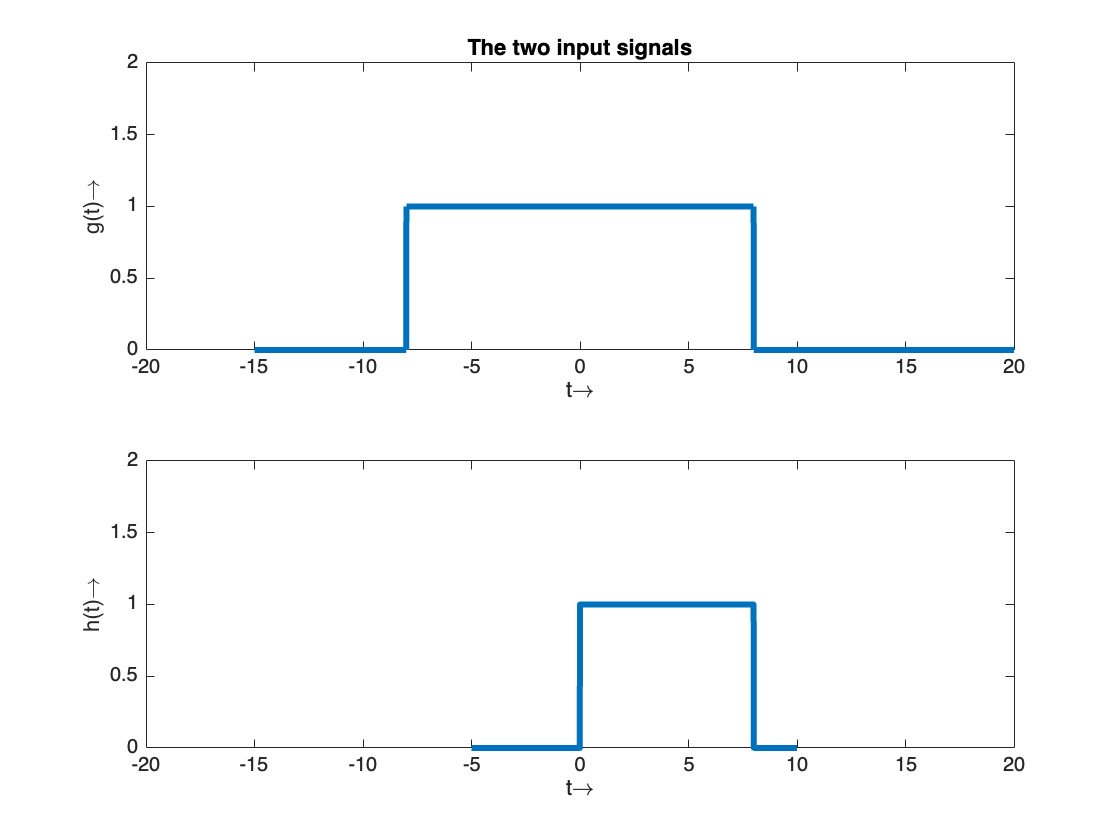

rect = @(t) double(abs(t)<=1/2);

Ts = 10e-3;
tg = -15:Ts:20;
g = @(t) rect(t/16);
th = -5:Ts:10;
h = @(t) rect((t-4)/8);

figure
ax1 = subplot(211);
plot(tg, g(tg), linewidth=3)
ylim([-inf 2])
xlabel('t\rightarrow')
ylabel('g(t)\rightarrow')
title('The two input signals')
ax2 = subplot(212);
plot(th, h(th), linewidth=3)
xlim([-20, 20])
ylim([-inf, 2])
xlabel('t\rightarrow')
ylabel('h(t)\rightarrow')
linkaxes([ax1, ax2])

Now, we can calculate the convolution of the two continuous-time signals by approximating the convolution integral through the rectangle rule, which is in turn the convulutional sum of the sampled versions of the respective signals:


$$y(t) = g(t)\ast h(t) = \int\limits_{-\infty}^{+\infty}g(\tau) \cdot h(t-\tau)\,\mathrm{d}\tau \approx  \sum\limits_{k = -\infty}^{+\infty} g[\kappa]\cdot h[k-\kappa] \cdot T_\mathrm{s} = y[k]\cdot T_\mathrm{s} = y(k\cdot T_\mathrm{s})$$


y = conv(g(tg), h(th))*Ts;

Now, the tricky part is to find the corresponding time vector for the resulting signal vector y. Since we use the conv() method with shape property set to 'full' (which is the default behaviour) the minimum time sample of $y(t)$ is given by the minimum time sample of $g(t)$ shifted to the minimum time sample of $h(t)$ (in our case this is `th(1)-(-tg(1))`). The sampling period remains evidently $T_\mathrm{s}$. For the convolution, the signal $h(t)$ is shifted through the complete signal $g(t)$ which means the maximum time sample for $y(t)$ is given by `th(1)+tg(1)+(tg(end)-tg(1))+(th(end)-th(1))=tg(end)+th(end)`.

ty = th(1)+tg(1):Ts:tg(end)+th(end);

Having the convolved signal `y` and the corresponding time vector `ts`, it is now possible to plot the signal $y(t)$.

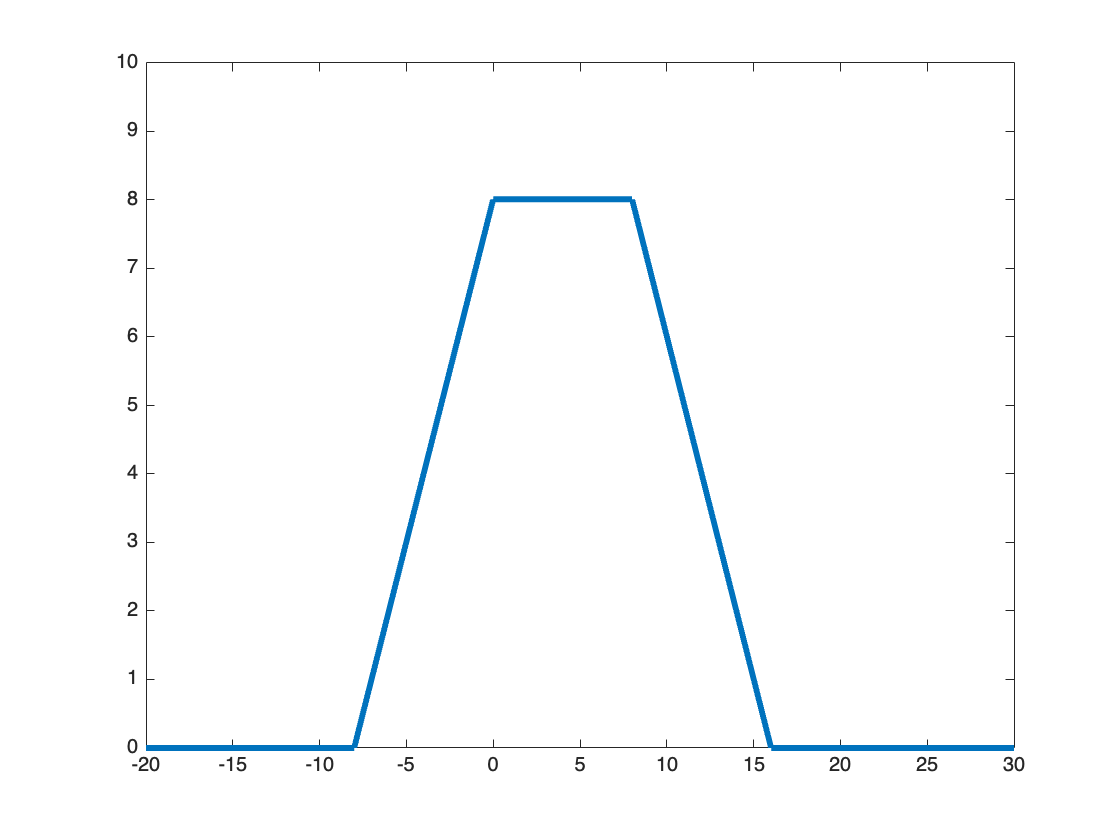

figure
plot(ty, y, linewidth=3)
ylim([-inf 10])

### Animation of the convolution of two rectangular signals

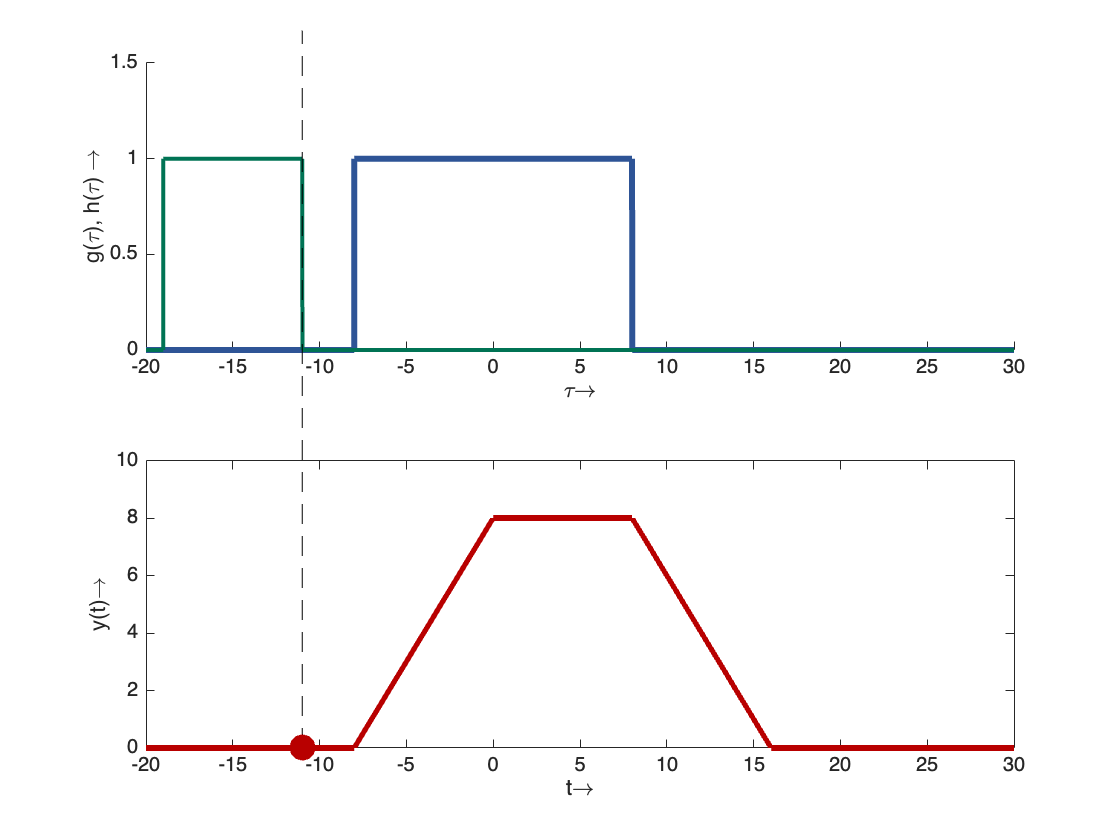

t =-11;
figure
green = [0, 0.45, 0.33];
blue = [0.18, 0.33, 0.59];
red = [0.72, 0, 0];
tau = ty;
ax1 = subplot(211);
t_overlap = tau(g(tau).*h(t-tau)>0);
if ~isempty(t_overlap)
    patch(t_overlap([1, end, end, 1]), [0, 0, 1, 1], red, facealpha=0.5)
end
hold on
plot(tau, g(tau), color=blue, linewidth=3)
plot(tau, h(t-tau), color=green, linewidth=2)
xlabel('\tau\rightarrow')
ylabel('g(\tau), h(\tau) \rightarrow')
ylim([-inf, 1.5])
ax2 = subplot(212);
y0 = @(t) sum(g(tau).*h(t-tau))*Ts;
plot(ty, y, linewidth=3, color=red)
hold on
plot([t, t], [0, 25], 'k--')
plot(t, y0(t), color=red, marker='.', linewidth=3, markersize=45)
set(ax2, clipping='off')
ylim([-inf, 10])
xlabel('t\rightarrow')
ylabel('y(t)\rightarrow')
linkaxes([ax1, ax2], 'x')

### Convolution of rectangular signal with dirac impulse

The convolution of a signal with a dirac impulse leads to a shift of the signal to the time position of the dirac impulse together with a multiplication of the weighting of the dirac. Implementing such a convolution in Matlab works a little bit different to the one described above. In our example we consider again the signal $h(t)$ from our example above and calculate the convolution with a dirac at time $t=5$


$$z(t) = h(t) \ast \delta(t-5)$$


Before we can implement the dirac impulse in matlab we have to look at one of its mathematical definitions


$$\delta(t) = \lim_{T\to 0} \,\frac{\mathrm{rect}\left(1/T\right)}{T}$$


Using this definition the integral


$$\int\limits_{-\infty}^{+\infty} \delta(t)\,\mathrm{d}t = 1$$


That means, the dirac impulse is a rectangluar impulse with infinite height and zero width. It is not feasible to implement such an impulse in Matlab. However we can approximate this impulse by an impulse with width of our sampling period $T_\mathrm{s}$ and the weighting height (in our case it would be one).


$$\delta(t) \approx \frac{\mathrm{rect}\left(1/T_\mathrm{s}\right)}{T_\mathrm{s}}$$


When using this definition, we have to be careful when plotting the dirac impulse. It is now necessary to multiply the dirac with the sampling time in order to show the correct weighting.

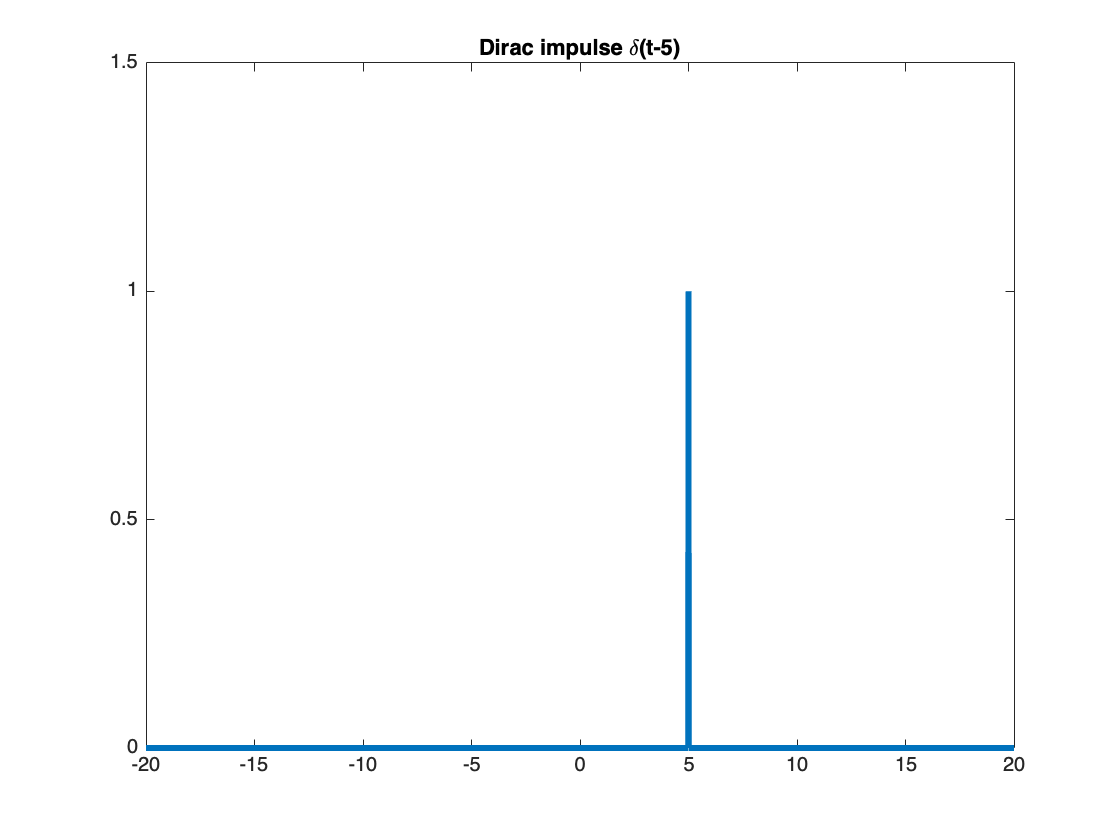

dirac = @(t) (abs(t)<=Ts/2)/Ts;
d5 = @(t) dirac(t-5);
td5 = -20:Ts:20;

figure
plot(td5, d5(td5)*Ts, linewidth=3)
ylim([-inf, 1.5])
title('Dirac impulse \delta(t-5)')

The calculation of the convolution $z(t)$ is now done in the same way as described above.

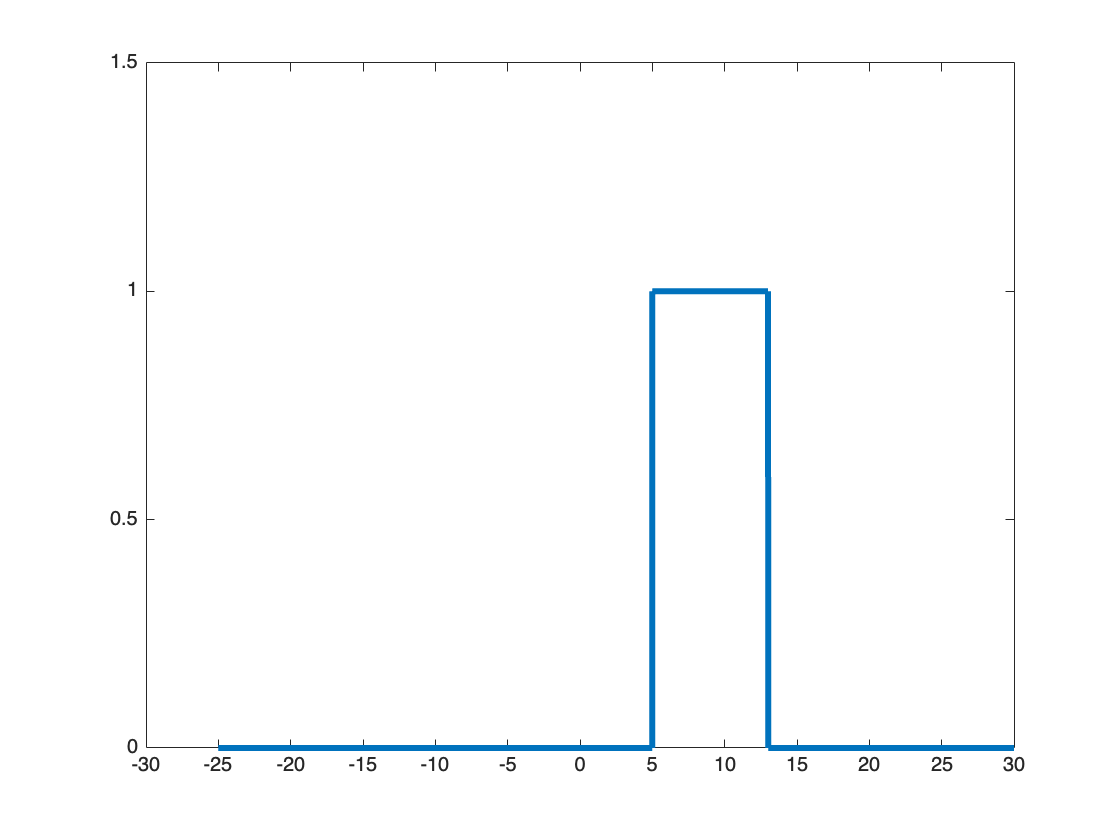

z = conv(h(th), d5(td5))*Ts;
tz = th(1)+td5(1):Ts:th(end)+td5(end);

figure
plot(tz, z, linewidth=3)
ylim([-inf, 1.5])
set(gca, 'Xtick', -30:5:30)